%% Sample Data information
% datanz.imagenames = {'02-12-2016_21_20_17_top.fits';...
%                      '02-12-2016_21_19_27_top.fits';...
%                      '02-12-2016_21_18_37_top.fits' };
% datanz.imagenames = {'02-15-2016_21_04_37_top.fits'};
% datanz.imagenames = {'02-12-2016_23_40_04_top.fits';...
%                      '02-12-2016_23_38_22_top.fits';...
%                      '02-12-2016_23_29_11_top.fits' };
datanz.imagenames =  {'02-21-2016_01_55_21_top.fits'};
datanz.totalimages = length(datanz.imagenames);              
datanz.greenevap = 0.07;
datanz.irevap = 1;
datanz.seqmode = 21;
datanz.roi_rect = [217, 110, 324-217, 330-110];
datanz.pixelonatom = 1.44*10^-6;
datanz.trapomega = 2*pi*23.9;
datanz.massLi6 = 9.988346*10^-27;
datanz.sigma0 = 6*pi*((671*10^-9)/(2*pi))^2;
datanz.h = 6.62607004*10^-34;
datanz.hbar = datanz.h / (2*pi);


%% Load sample data
if 0 || ~isfield(datanz,'a')
    datapath = 'J:\Elder Backup Raw Images\2016\2016-02\2016-02-20';
    
    datanz.raw_imdata{1} = load_img2(fullfile(datapath,datanz.imagenames{1}), datanz.roi_rect);
    datanz.averageOD = datanz.raw_imdata{1} / datanz.totalimages;
    
    for imnum = 2:datanz.totalimages
        datanz.raw_imdata{imnum} = load_img2(fullfile(datapath,datanz.imagenames{imnum}), datanz.roi_rect);
        datanz.averageOD = datanz.averageOD + datanz.raw_imdata{imnum} / datanz.totalimages;
    end
    
end

   -0.1247



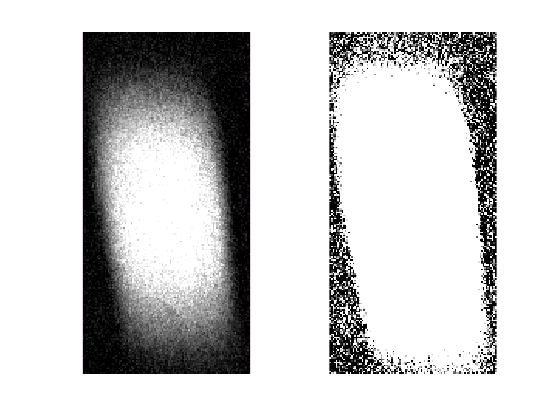


datanz.z = (1:1:size(datanz.averageOD,1))' * datanz.pixelonatom;

figure; ax1 = subplot(1,2,1);
imshow(datanz.averageOD,[0 1.5]); set(ax1,'YDir','normal');
ax2 = subplot(1,2,2);
imshow(datanz.averageOD,[0 0.1]); set(ax2,'YDir','normal');

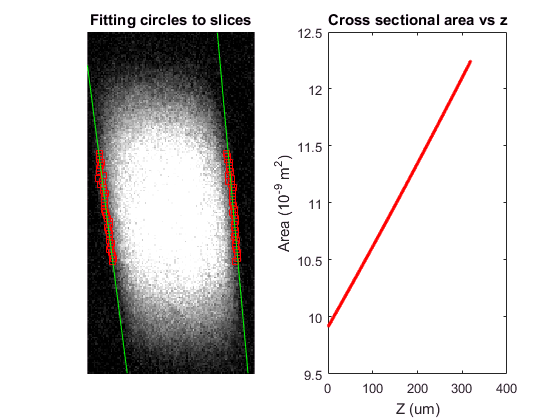

%% Cross sectional area
datanz.xsec.ycuts = (73:2:143)';
[datanz.xsec_area, datanz.corrected_data] = get_xsection_area(datanz.averageOD,datanz.xsec.ycuts,datanz.pixelonatom);

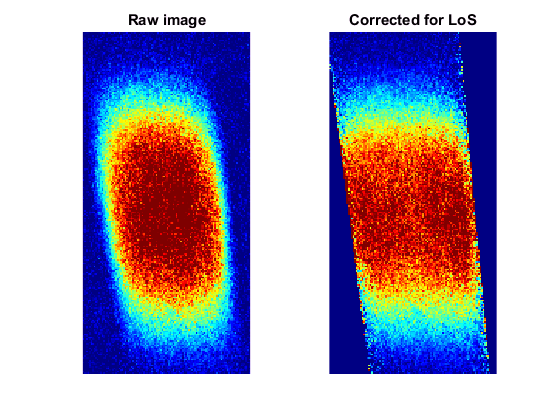

%% Flattening

datanz.corrected_data(isinf(datanz.corrected_data))=0;

figure;
ax3 = subplot(1,2,1);
imshow(datanz.averageOD,[0 1.7]); set(ax3,'YDir','normal');axis image; title('Raw image');
ax1 = subplot(1,2,2); 
imshow(datanz.corrected_data,[0 0.05]); set(ax1,'YDir','normal'); axis image; title('Corrected for LoS');
colormap jet

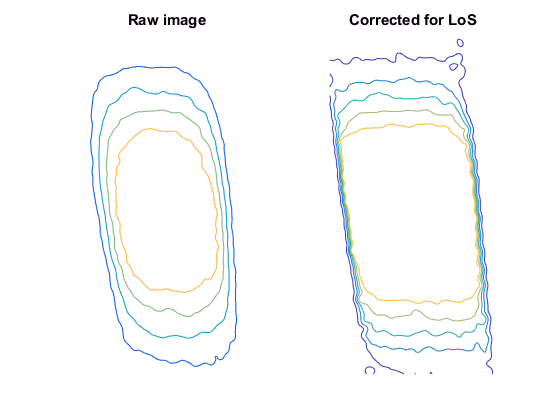


figure

datanz.corrected_data_smooth = imgaussfilt(datanz.corrected_data,2);
datanz.corrected_data_smooth = datanz.corrected_data_smooth *(max(datanz.averageOD)/max(datanz.corrected_data_smooth));
datanz.averageOD_smooth = imgaussfilt(datanz.averageOD,2);

ax2 = subplot(1,2,2);
contour(datanz.corrected_data_smooth,0.1:1.1/4:1.42); set(ax2,'YDir','normal'); axis image; axis off;title('Corrected for LoS');
caxis([0 1.4])
ax4 = subplot(1,2,1);
contour(datanz.averageOD_smooth,0.2:1.5/4:1.6); set(ax4,'YDir','normal','LineWidth',2); axis image;  axis off;title('Raw image');
colormap parula
caxis([0 1.6])








%% variance in atom numbers
% figure;
% plot(datanz.z/datanz.pixelonatom,var(datanz.corrected_data(:,25:85),0,2),'r.');

% figure;
% contour(wiener2(datanz.corrected_data,[3,3]),0:0.006:0.04); set(ax2,'YDir','normal'); 

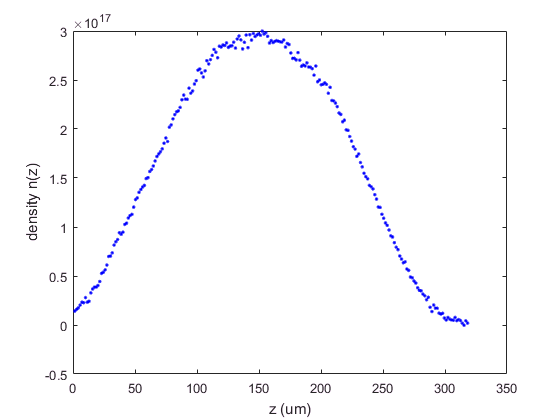

%% Integrated profiles and TF fits
datanz.n_z = sum(datanz.averageOD,2) ./ (datanz.xsec_area / datanz.pixelonatom * (datanz.sigma0 / 2)) * 1.837;
figure; plot(datanz.z * 10^6, datanz.n_z,'b.'); xlabel('z (um)'); ylabel('density n(z)');

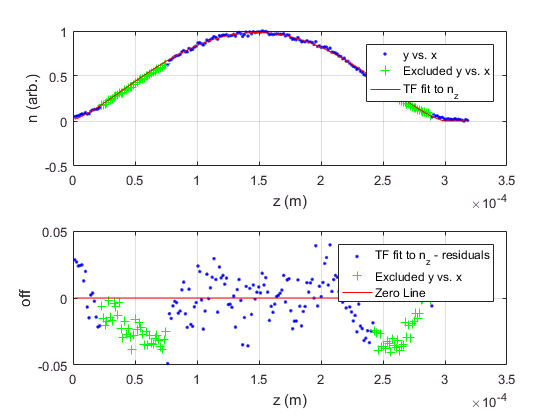


% Fitting variables
x = datanz.z; y = datanz.n_z;
fitres = createFitTFnz(x,y); datanz.z0 = fitres.x0;

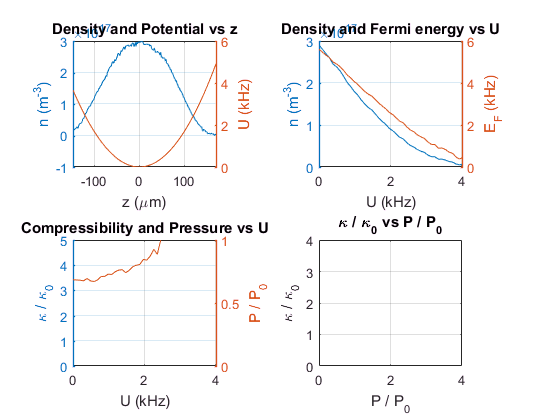

z_i = datanz.z - fitres.x0;
n_z = datanz.n_z;
[k_U, P_U, U_i, EF_U, n_U] = EoS_nz_KvsP(z_i,n_z,'plot_maxU',4,'bins',50);

%% n(V)
datanz.potential = 1/2*datanz.massLi6*datanz.trapomega^2 * (datanz.z - datanz.z0).^2;
figure;
plot(datanz.z*10^6, datanz.potential/datanz.h/1000,'r.'); xlabel('z (um)'); ylabel(' V (kHz)'); title('Trap potential');
figure;
plot(datanz.potential/datanz.h/1000,datanz.n_z,'r.'); xlabel('V (kHz)'); ylabel(' n (m^{-3})'); title('Raw n[V]');
%% Bin n(V)
totalbins = 50;
datanz.V = (0:max(datanz.potential)/totalbins:max(datanz.potential))';
locs = discretize(datanz.potential,datanz.V);
datanz.n_V = zeros(size(datanz.V));
datanz.n_V_std = zeros(size(datanz.V));
for i = 1:length(datanz.V)
    ithbin = [];
    for j = 1:length(datanz.n_z)
        if locs(j) == i
            ithbin = [ithbin, datanz.n_z(j)];
        end
    end
    datanz.n_V(i) = mean(ithbin);
    datanz.n_V_std(i) = std(ithbin);
end
errorbar(datanz.V/datanz.h/1000,datanz.n_V,datanz.n_V_std,'r.');  xlabel('V (kHz)'); ylabel(' n (m^{-3})'); title('Binned n[V]'); xlim([0 4.5]);

%% Get fermi energy and kappa
datanz.EF_V = datanz.hbar^2 / (2*datanz.massLi6) * (6*pi*datanz.n_V).^(2/3);
figure;
plot(datanz.V/datanz.h/1000,datanz.EF_V/datanz.h/1000,'r.');  xlabel('V (kHz)'); ylabel(' E_F (kHz)'); title('Ferrmi energy E_F[V]'); 
% kappa of pressure
datanz.kappanorm_V = - diff(datanz.EF_V) ./ diff(datanz.V);
plot(datanz.V(2:end)/datanz.h/1000,datanz.kappanorm_V,'r-');  xlabel('V (kHz)'); ylabel(' \kappa / \kappa_0'); title('\kappa / \kappa_0 [V]'); 
% Pnorm(V)
datanz.Pnorm_V = zeros(size(datanz.V));
for i = 1:length(datanz.Pnorm_V)
    datanz.Pnorm_V(i) = (sum(datanz.n_V(i:end-1))* (datanz.V(2) - datanz.V(1))) / (2/5*datanz.n_V(i)*datanz.EF_V(i));
end
figure;
plot(datanz.V/datanz.h/1000,datanz.Pnorm_V,'r.');  xlabel('V (kHz)'); ylabel(' P / P_0'); title('P / P_0 [V]'); ylim([0 10]); xlim([0 2]);

figure;
plot(datanz.Pnorm_V(2:end),datanz.kappanorm_V,'r.');  xlabel('P / P_0'); ylabel(' \kappa / \kappa_0'); title('\kappa / \kappa_0 vs. P / P_0'); ylim([0 2]); xlim([0 10]);


%%